# 3. Identification of pump response and 3-way valves $\gamma$

## Procedure

It is convenient to model the pump flow as $q = ku$, where $q$ is the flow, and $u$ is the pump input with stauration $[u_{min};u_{max}]$. It is known that the curve $q(PWM)$ can be approximated by 

$q(PWM) = ku = c_1\frac{PWM-c_3}{PWM-c_2}$,

the PWM input $PWM$ is considered to be normalised to the range $[0;1]$. Thus, first the parameters of the curve $q(PWM)$, and then k is computed with a transformation between $u$ and $PWM$, i.e.,

$k = q_{max}/u_{max}=  \frac{c_1(1-c_3)}{u_{max}(1-c_2)}$, and


$$PWM = \frac{c_1c_3-c_2ku}{c_1-ku}$$


For the identification of the response of the pumps and the fraction of flow that is diverted on the three way valves the following procedure is proposed.

Note: The identification of $A_1,...,A_4$ is required.

1 . Open '**identification_sl.slx**';

For each actuation pump (exemplified with pump 1 below):

2. Block the outlets of the lower tanks. (Either close the valves or block the oulet with a finger). Note that, depending on the quality of the 3D print, the valves may have a small leak, so the second method is recomended;

3. Send a PWM input to pump 1, wait until tank 1 almost full then turn of the pump.

4. Let tank 4 pour all the water into tank 2 (whose outlet is still blocked).

5. For that particular $PWM$ values measure the heght of the tanks $h_1$ and $h_2$, in the scope measure the interval of time the pump was on $\Delta t$.

6. Repeat 4. for various $PWM$values, the pump is most sensive for low PWM values 50-150, so a greater sample density in this region is beneficial.

Note: the pump may not start from $q=0$ to a small value of $PWM$. To mantain the pump at a small values of $PWM$ is necessary to instantly provide a large $PWM$ value and decrease afterwards to the desired value.

7. From the samples computed, $q = h_1A_1+h_2A_2$, and  $\gamma = h_1A_1/(h_1A_1+h_2A_2)$, it is then possible to find the constants $c_1,c_2,c_3$ and $k$ from a nonlinear least squares regression, for instance.

The procedure is similar for the disturbance pumps.

## Initialization

clear;
load("./data/A.mat");

## Pump 1

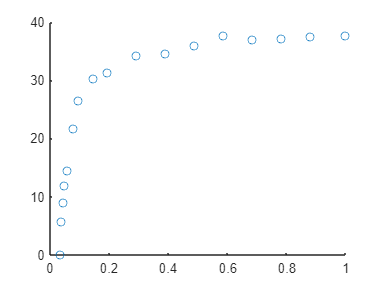

pwm = [1023;900;800;700;600;500;400;300;200;150;100;80;60;50;45;40;35]/1023;
h1 = [26.9;26.8;27.4;27.3;27.9;27.5;27.3;27.2;27.1;27.8;26.9;27.6;27.0;27.1;27.3;27.3;1];
h2 = [8.5;8.5;8.7;8.7;8.8;8.7;7.6;8.5;8.7;8.9;8.6;8.8;9.0;9.6;10.1;8.6;0];
dt = [28;28;29;29;29;30;30;31;34;36;40;50;74;92;124;184;inf];
% Compute flow
q = (A(1)*h1+A(2)*h2)./dt; % cm^3/s
% Plot flow vs normalized PWM
figure();
scatter(pwm,q);

% Initial guess for least squares
c0 = [40;0;0.04];
sqError = @(c) q-(c(1)*(pwm-c(3))./(pwm-c(2)));
% Solve least squares optimization problem
c_sol = lsqnonlin(sqError,c0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


c_sol =    39.0102
   -0.0012
    0.0339


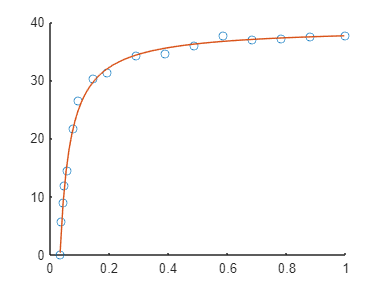

% Plot data and fitted curve
figure;
hold on;
scatter(pwm,q);
plot((min(pwm):0.01:max(pwm)),c_sol(1)*((min(pwm):0.01:max(pwm))-c_sol(3))./((min(pwm):0.01:max(pwm))-c_sol(2)));

% Set u_max
u1_max = 12; %(V)
q1_max = c_sol(1)*(1-c_sol(3))/(1-c_sol(2))

q1_max = 37.6428

u1_min = 0

u1_min = 0

k1 = q1_max/u1_max %(cm^3/s/V)

k1 = 3.1369

c1 = c_sol;

## Gamma 1

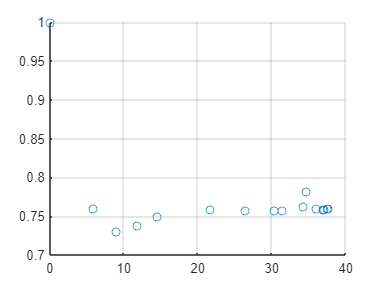

% Compute gamma
gamma1 = A(1)*h1./(A(1)*h1+A(2)*h2);
% Plot data
figure();
hold on;
scatter(q,gamma1);
grid on;

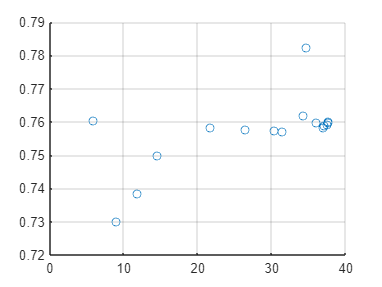

% Remove outliers
gamma1_out = gamma1(gamma1<0.8);
q_out = q(gamma1<0.8);
% Plot data without outliers
figure();
hold on;
scatter(q_out,gamma1_out);
grid on;

% Compute coefficient of variation
cv_gamma1 = sqrt(var(gamma1_out))/mean(gamma1_out)

cv_gamma1 = 0.0146

% Compute average gamma
gamma1 = mean(gamma1_out)

gamma1 = 0.7569

## Pump 2

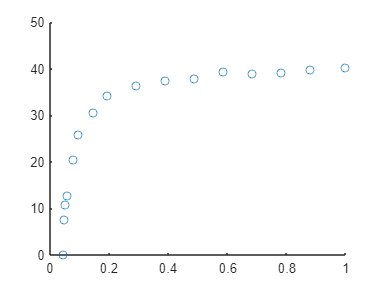

pwm = [1023;900;800;700;600;500;400;300;200;150;100;80;60;55;50;45]/1023;
h1 = [8.6;8.4;8.3;8.3;8.4;8.3;8.7;8.3;8.2;8.1;6.4;6.2;9.3;10.3;11.2;0];
h2 = [27.8;27.6;27.2;27.0;27.2;27.3;27.8;27.1;27.4;26.7;27.5;27.4;26.6;27.3;27.3;1];
dt = [27;27;27;27;27;28;29;29;31;34;39;49;84;104;151;inf];
% Compute flow
q = (A(1)*h1+A(2)*h2)./dt; % cm^3/s
% Plot flow vs normalized PWM
figure();
scatter(pwm,q);

% Initial guess for least squares
c0 = [40;0;0.04];
sqError = @(c) q-(c(1)*(pwm-c(3))./(pwm-c(2)));
% Solve least squares optimization problem
c_sol = lsqnonlin(sqError,c0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


c_sol =    41.1491
    0.0099
    0.0430


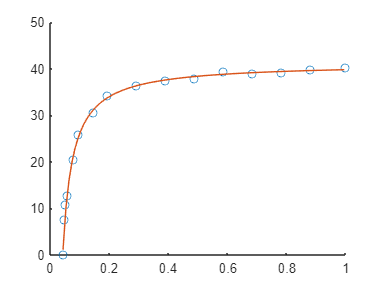

% Plot data and fitted curve
figure;
hold on;
scatter(pwm,q);
plot((min(pwm):0.01:max(pwm)),c_sol(1)*((min(pwm):0.01:max(pwm))-c_sol(3))./((min(pwm):0.01:max(pwm))-c_sol(2)));

% Set u_max
u2_max = 12; %(V)
q2_max = c_sol(1)*(1-c_sol(3))/(1-c_sol(2))

q2_max = 39.7708

u2_min = 0

u2_min = 0

k2 = q2_max/u2_max %(cm^3/s/V)

k2 = 3.3142

c2 = c_sol;

## Gamma 2

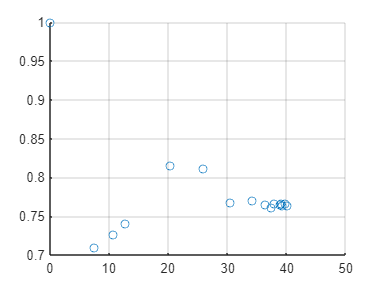

% Compute gamma
gamma2 = A(2)*h2./(A(1)*h1+A(2)*h2);
% Plot data
figure();
hold on;
scatter(q,gamma2);
grid on;

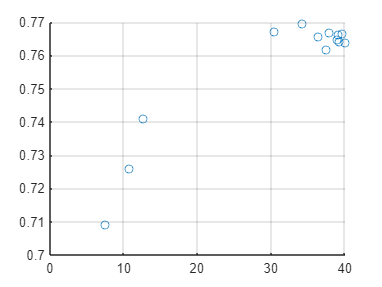

% Remove outliers
gamma2_out = gamma2(gamma2<0.8);
q_out = q(gamma2<0.8);
% Plot data without outliers
figure();
hold on;
scatter(q_out,gamma2_out);
grid on;

% Compute coefficient of variation
cv_gamma2 = sqrt(var(gamma2_out))/mean(gamma2_out)

cv_gamma2 = 0.0250

% Compute average gamma
gamma2= mean(gamma2_out)

gamma2 = 0.7563

## Save data

% Save gamma
gamma = [gamma1; gamma2];
cv_gamma = [cv_gamma1; cv_gamma2];
save("./data/gamma.mat",'gamma','cv_gamma');
% Save pump response 
k = [k1;k2];
u_min = [u1_min; u2_min];
u_max = [u1_max; u2_max];
c = [c1 c2];
save("./data/pump.mat",'k','u_max','u_min','c');
